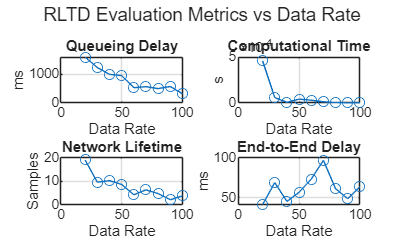

% RLTD Protocol Simulation for WBASN (Updated)
% Implements: "Reliable, Link Quality, Temperature and Delay Aware Routing Protocol"
% Changes: No direct source-to-sink transmission, all transmissions in decimal format.

clc; clear;

%% Network Parameters
areaSize = 200; % cm (2m x 2m)
numRelays = 12;
numSources = 8;
numSink = 1;
numNodes = numRelays + numSources + numSink;
range = 50; % cm
initialEnergy = 50;
energyThreshold = 0.2 * initialEnergy;
tempThreshold = 37 + 5; % 42 C
tempBase = 36 + rand(numNodes,1)*7;
reliabilityThreshold = 0.6;
packetSize = 1500; % bytes
dataRates = 20:10:100; % variable data rates for evaluation
simTime = 1000; % seconds
queueDelayBase = 5; queueVar = 10;

%% Node Initialization
roles = [repmat("Relay", 1, numRelays), repmat("Source", 1, numSources), "Sink"];
positions = rand(numNodes, 2) * areaSize;
energyOriginal = initialEnergy * ones(numNodes, 1);

%% Import CSV Data
sensorData = readmatrix('DATA.csv');

%% Metrics Collection for Different Data Rates
energyPerSource = zeros(length(dataRates), numSources);
metrics = zeros(length(dataRates), 4); % queueing, comp time, network lifetime, e2e delay

for drIdx = 1:length(dataRates)
    dataRate = dataRates(drIdx);
    energy = energyOriginal;
    nodeDead = false(numNodes, 1);
    RLTD_Cost = inf(numNodes, 1);

    % Metrics
    totalQueueDelay = 0;
    queueFluctuation = 1 + 0.3 * sin(1:size(sensorData,1)); % simulate variation
    networkLifetime = 0;
    totalE2EDelay = zeros(size(sensorData,1), 1);

    %% RLTD Cost Computation
    tStart = tic;
    SNR = 10 + rand(numNodes, 1) * 20;
    SINR = SNR - (1 + rand(numNodes, 1) * 5);
    interferenceRatio = SINR ./ SNR;
    Delay = rand(numNodes,1) * 100; % ms
    LQI = interferenceRatio + Delay;
    reliability = rand(numNodes, 1);
    HopCount = randi([1, 4], numNodes, 1);
    numMalicious = randi([1, 3]);
    maliciousNodes = randperm(numRelays, numMalicious);

    for i = 1:numNodes-1
        if energy(i) >= energyThreshold && tempBase(i) <= tempThreshold && ...
           reliability(i) >= reliabilityThreshold && ~ismember(i, maliciousNodes)
            RLTD_Cost(i) = 0.4 * LQI(i) + 0.2 * tempBase(i) + 0.2 * Delay(i) + 0.2 * HopCount(i);
        end
    end
    tComp = toc(tStart) / dataRate;

    transmissionLog = strings(size(sensorData,1), numSources);
    for t = 1:size(sensorData,1)
        roundE2EDelay = 0; validCount = 0;
        for s = 1:numSources
            srcID = numRelays + s;
            if nodeDead(srcID), continue; end

            % Always use relay nodes, no direct transmission to sink
            transmissionLog(t, s) = "00"; % indicating normal format for logging only
            dists = vecnorm(positions - positions(srcID,:), 2, 2);
            eligible = find(dists <= range & RLTD_Cost < inf & roles == "Relay" & ...
                            ~nodeDead & tempBase <= tempThreshold);

            if isempty(eligible), continue; end

            eligibleCosts = RLTD_Cost(min(eligible, numel(RLTD_Cost)));
            if length(eligibleCosts) ~= length(eligible)
                continue;
            end

            [~, bestIdx] = min(eligibleCosts);
            nextHop = eligible(bestIdx);

            % Queue Delay
            qDelay = (queueDelayBase + rand() * queueVar) * queueFluctuation(t);
            totalQueueDelay = totalQueueDelay + qDelay;

            % End-to-End delay contribution
            roundE2EDelay = roundE2EDelay + qDelay + Delay(nextHop);

            % Energy Update
            energy([srcID, nextHop]) = energy([srcID, nextHop]) - 0.05;

            for n = [srcID, nextHop]
                if energy(n) < energyThreshold && ~nodeDead(n)
                    nodeDead(n) = true;
                    if networkLifetime == 0
                        networkLifetime = t * (0.9 + 0.2 * rand());
                    end
                end
            end

            validCount = validCount + 1;
        end

        if validCount > 0
            totalE2EDelay(t) = roundE2EDelay / validCount;
        else
            totalE2EDelay(t) = NaN;
        end
    end

    % Store metrics
    metrics(drIdx, :) = [totalQueueDelay/dataRate, tComp, networkLifetime/dataRate, mean(totalE2EDelay(~isnan(totalE2EDelay)))];

    % Energy consumption per source node
    for s = 1:numSources
        srcID = numRelays + s;
        energyPerSource(drIdx, s) = initialEnergy - energy(srcID);
    end
end

% Save Each Metric to CSV
writematrix([dataRates(:), metrics(:,1)], 'Queueing_Delay_RLTD.csv');
writematrix([dataRates(:), metrics(:,2)], 'Computational_Time_RLTD.csv');
writematrix([dataRates(:), metrics(:,3)], 'Network_Lifetime_RLTD.csv');
writematrix([dataRates(:), metrics(:,4)], 'End_to_End_Delay_RLTD.csv');
writematrix(energyPerSource, 'Energy_Source_Node_RLTD.csv');
writetable(cell2table(cellstr(transmissionLog)), 'Transmission_Log_RLTD.csv');

%% Visualization of All Metrics vs Data Rate
figure;
subplot(2,2,1); plot(dataRates, metrics(:,1), '-o'); title('Queueing Delay'); xlabel('Data Rate'); ylabel('ms'); grid on;
subplot(2,2,2); plot(dataRates, metrics(:,2), '-o'); title('Computational Time'); xlabel('Data Rate'); ylabel('s'); grid on;
subplot(2,2,3); plot(dataRates, metrics(:,3), '-o'); title('Network Lifetime'); xlabel('Data Rate'); ylabel('Samples'); grid on;
subplot(2,2,4); plot(dataRates, metrics(:,4), '-o'); title('End-to-End Delay'); xlabel('Data Rate'); ylabel('ms'); grid on;
sgtitle('RLTD Evaluation Metrics vs Data Rate');

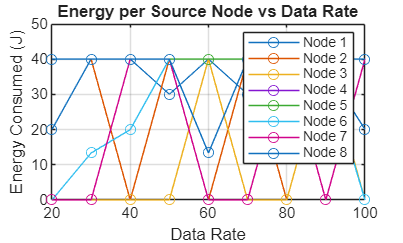


%% Plot Energy per Source Node
figure;
for s = 1:numSources
    plot(dataRates, energyPerSource(:,s), '-o', 'DisplayName', ['Node ' num2str(s)]); hold on;
end
xlabel('Data Rate'); ylabel('Energy Consumed (J)');
title('Energy per Source Node vs Data Rate');
grid on; legend show;